# CAŁKOWANIE i RÓŻNICZKOWANIE

## Ogólne zagadnienia wymagane na laboratorium nr 4

## "Wstęp do metod numerycznych"

Opracował: K. Król i M. Kamiński

**---------------------------------------------------------------------------------------------------------------------------------------------**

**UWAGA! Zaleca się pracować z niniejszym skryptem ustawiając opcję "View" -> "Output on Rigth"**

**---------------------------------------------------------------------------------------------------------------------------------------------**

**Umiejętności wymagane na laboratorium**

Na laboratorium wymagany jest cały zakres wiedzy wykładowej ze szczególnym uwzględnieniem tematyki całkowania i różniczkowania numerycznego. W podstawowym zakresie sprawdzane będzie:

- Czy student potrafi zaimplementować proste metody numerycznego różniczkowania?

- Czy student rozumie zależność dokładności różniczkowania od długości kroku i pojęcie kroku optymalnego? Także przyczyny jego powstania?

- Czy student zna postać kanoniczną problemu całkowania numerycznego - co to jest i jak jest zbudowana kwadratura, jak się ją implementuje?

- Czy student rozumie jakie są właściwości podstawowych kwadratur i skąd się biorą - pochodzenie kwadratur od interpolacji, i wynikające z tego właściwości?

- Czy student rozumie pojęcie rzędu kwadratury i jego wpływu na wynik obliczeń?

- Czy student rozumie co to jest zbieżność kwadratury i czy potrafi stwierdzić na podstawi wyników eksperymentów numerycznych czy dane kwadratury są zbieżne czy nie?

- Czy student umie zaimplementować dowolną kwadraturę złożoną?

- Czy student zna i umie zaimplementować podstawowe metody statystyczne całkowania (metody Monte Carlo), szczególnie w przypadkach do których są predysponowane np. całkowania w przestrzeni 3D?

- Czy student rozumie potrafi zbadać podstawowe właściwości numeryczne metod statystycznych całkowania?

        Dodatkowo:

- Czy student umie zaimplementować wybraną kwadraturę Gaussa - czy zna procedurę implementację takiej kwadratury?

Docelowo student powinien orientować się jakie ogólne właściwości mają poznane metody w świetle wszystkich problemów wymienionych powyżej. W związku z tym, że jest to pierwsze laboratorium dotyczące problemów związanych z parametrem numerycznym, jakim jest rząd metody, zrozumienie tego pojęcia będzie szczególnie istotne w kontekście poprawnego skomentowania otrzymanych wyników.

# PODPOWIEDZI IMPLEMENTACYJNE

## **Reprezentacja wielomianów w MATLAB**

Należy pamiętać, że w MATLAB wielomiany mogą być reprezentowane w specjalny sposób w postaci wektora współczynników od największego do najmniejszego. Przykładowo wektor:

A = [1 2 3 0 5];

może zostać zinterpretowany jako wielomian:


$$A=x^4+2x^3+3x^2+5$$


Największa potęga wynosi 4 ponieważ wektor A ma 5 elementów (piąty jest czynnik x^0=1 czyli czynnik stały). Zwróć uwagę: mimo, że w wielomianie nie występuje czynnik liniowy, to musi on być zapisany w wektorze jako 0 żeby interpretacja wektora jako wielomianu się udała, czyli *de facto*:


$$A=x^4+2x^3+3x^2+0x+5$$


Taki zapis wielomianów jest bardzo wygodny w użytkowaniu. na takim zapisie wielomianów działają funkcje, których nazwy zaczynają się od ***poly...*** np.:

- ***polyint()*** - zwraca wektor współczynników wielomianu będącego całką z wielomianu wejściowego

- ***polyder()*** - zwraca wektor współczynników wielomianu będącego pochodną z wielomianu wejściowego

- ***polyval()*** - zwraca wartości wielomianu opisanego współczynnikami w wybranych punktach

- ***polyfit()*** - wykonuje interpolację bądź aproksymację wielomianową, zwracając wynik w postaci wektora współczynników wielomianu

% Przykładowo 

A = [1 2 3 0 5];

Wielomian: $A=x^4+2x^3+3x^2+5$

A_calka = polyint(A)

A_calka =    2.0000e-01   5.0000e-01   1.0000e+00            0   5.0000e+00            0


Czyli wielomian: $A_{calka}=\frac{1}{5}x^5+\frac{1}{2}x^4+1x^3+0x^2+5x+0$

A_pochodna = polyder(A)

A_pochodna =      4     6     6     0


Czyli wielomian: $A_{pochodna}=4x^3+6x^2+6x+0$

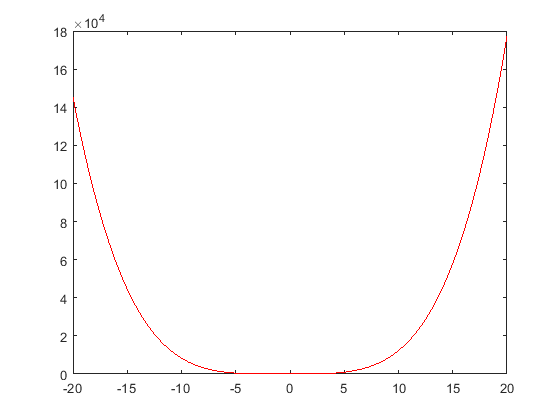

% Jeżeli byśmy chcieli wyrysować wielomian A to mozemy zrobić to tak:

x=[-20:0.01:20];

plot(x,polyval(A,x),'r');

## Podstawowa kwadratura i jej implementacja

Podstawową metodą obliczania numerycznego całki, jaką będziemy zajmować się na laboratorium, jest obliczenie kwadratury numerycznej, czyli całki w formie:


$${\overset{~}{I} }_N {\left(f\right)}=\sum_{k=1}^N A_k f\left(x_k \right)$$


Niezależnie od tego jak wyznaczane, albo skąd brane będą współczynniki kwadratury w MATLAB zawsze można bardzo łatwo ja zaimplementować, jeżeli się zauważy, że powyższy wzór można zapisać w formie wektorowej, jako iloczyn skalarny dwóch wektorów (co odpowiada mnożeniu wektora przez wektor transponowany):


$${\overset{~}{I} }_N {\left(f\right)}=\mathit{\mathbf{A}}\cdot \mathit{\mathbf{f}}=\mathit{\mathbf{A}}\;{\mathit{\mathbf{f}}}^T$$


wektor ***A*** zawiera współczynniki kwadratury, a wektor ***f*** wartości węzłów kwadratury. Ponieważ MATLAB przystosowany jest do obliczeń macierzowych taka forma implementacji nie wymaga żadnego indeksowania i jest znacznie prostsza i szybsza w uruchomieniu niż implementacja z pętlą ***for***.

Przykładowo całka z funkcji  $x^2$ w przedziale [0,1] wynosi:


$$I=\int_0^1 x^2 \;\mathrm{dx}=\underset{\left\lbrack 0,1\right\rbrack }{\frac{1}{3}x^3 } =\frac{1}{3}$$


Obliczmy ją za pomocą 4 punktowej kwadratury  Newtona-Cotesa:

% Współczynniki kwadratury Newtona-Cotesa odczytujemy z tabelki i
% odpowiedniego wzoru:


$$A_k =A_{k,N} =\left(b-a\right)\frac{l_{k,N} }{m_N }$$


N=4;        %liczba węzłów kwadratury
m_N = 8;    %współczynnik znany z literatury 
lk_N=[1 3 3 1];  %współczynniki znane z literatury 
a=0;        %lewa krawędź przedziału całkowania
b=1;        %prawa krawędź przedziału całkowania


%Obliczenie wektora współczynników:
Ak=(b-a).*(lk_N)./(m_N);

%Węzły kwadratury
f = @(x) x.^2;          %definicja funkcji anonimowej, tu dla przykładu prosta funkcja kwadratowa. W przypadku wielomianu wystarczy zdefiniować wektor współczynników. Tutaj: fWsp=[1 0 0]
xw=linspace(a,b,N);     %definicja współrzędnych x węzłów kwadratury
yw=f(xw);               %w przypadku wielomianu: yw=polyval(fWsp,xw)

format shortE   %wyświetlanie liczb w formacie inżynierskim

%Obliczenie kwadratury Newtona-Cotesa opartej na 4 węzłach (metoda 3/8)
I_NC4 = sum(Ak.*yw)        %iloczyn skalarny, jeszcze prościej można I_NC4=Ak*yw'

I_NC4 =    3.3333e-01



%Zwróć uwagę, że kod jest napisany elastycznie - może być łatwo
% dostosowany do innego problemu (innej funkcji podcałkowej lub
% przedziału calkowania) - wystarczy zmienić definicję funkcji
% (lub współczynników wielomianu) i krawędzi przedziału. Inaczej
% mówiąc nic nie jest "zahardkodowane".

 

Oczywiście gdybyśmy chcieli obliczyć wartość dokładną całki analitycznie (za pomocą wzoru Newtona-Leibnitza):


$$\int_a^b f\left(x\right)=F\left(b\right)-F\left(a\right)$$


to trzeba wyznaczyć całkę nieoznaczoną $F\left(x\right)$, co nie zawsze się da zrobić w sposób łatwy. W naszym przypadku postać funkcji pierwotnej $F\left(x\right)$ możemy szybko uzyskać (bo jest wielomianem) - skorzystamy w tym celu z funkcji MATLAB ***polyint(). ***Przykładowo zastosujemy obliczenie wartości dokładnej do wyznaczenia błędu wcześniej obliczonej całki:

%Zapis funkcji podcałkowej w notacji wielomianowej MATLAB:
fWsp = [1 0 0];   %odpowiada 1*x^2+0*x+0

%Obliczenie współczynników funkcji pierwotnej:
FWsp = polyint(fWsp)

FWsp =    3.3333e-01            0            0            0



%Obliczenie całki analitycznie:
I_dokl = polyval(FWsp,b)-polyval(FWsp,a)

I_dokl =    3.3333e-01



%Obliczenie błędu bezwzględnego
blad = abs(I_NC4-I_dokl)                %w naszym przykładzie błąd powinien wynieść zero, bowiem kwadratura oparta na czterech węzłach, pozwala obliczyć dokładnie całkę z każdego wielomianu stopnia <= 3.

blad =      0


## Moduł obliczeń symbolicznych

Jeżeli czujesz się słabo w obliczeniach na papierze całek z funkcji, to zawsze możesz wykorzystać MATLABA do obliczenia quasi-analitycznego (inne popularne narzędzia programistyczne do obliczeń quasi-analitycznych to np. WolframAlpha lub Mathematica) - inna nazwa takich obliczeń, to obliczenia symboliczne. Najczęściej będziemy ich używać do wyznaczenia błędu, tak jak w przykładowym kodzie powyżej. MATLAB zawiera bowiem toolbox Symbolic Math Toolbox pozwalający na wykonywanie obliczeń symbolicznych (algebraicznych). Poniżej przykład jak się go używa:

% Po pierwsze musimy zadeklarować zmienną która będzie uważana za
% symboliczną, oznaczmy ja x_sym, zeby nie miec później problemu z
% nazwami zmiennych. Zmienne symboliczne i zwykłe nie mogą być użyte w
% sensownym wyrażeniu MATLABA razem:
syms x_sym

%Od teraz każde użyce zmiennej x_sym będzie dawało w rezultacie obiekt
%symboliczny. Przyjmijmy, ze nasza funkcja podcałkowa to:

f_x_sym = exp(x_sym)*x_sym

$$f\_x\_sym = x_{\mathrm{sym}}\,{\mathrm{e}}^{x_{\mathrm{sym}}}$$


%jak widzisz teraz f_x_sym to obiekt symboliczny zawierający funkcję
%możemy policzyć funkcję pierwotną przez:
F_x_sym = int(f_x_sym)

$$F\_x\_sym = {\mathrm{e}}^{x_{\mathrm{sym}}}\,\left(x_{\mathrm{sym}}-1\right)$$


%Obliczyliśmy całkę nieoznaczoną z dokładnością do stałej. Gdy chcemy obliczyć 
% calkę nieoznaczoną (np. na przedziale [1;2]),
a=1; b=2;
% to musimy obliczyć wartość funkcji pierwotnej w punkcie, robimy to:
x_sym=b;
F_b=subs(F_x_sym)   %komenda podstawia liczbową wartość x_sym do wyrażenia F_x_sym (ale wynik dalej ma postać wyrażenia symbolicznego)

$$F\_b = {\mathrm{e}}^{2}$$

x_sym=a;
F_a=subs(F_x_sym)

$$F\_a = 0$$

I=double(F_b-F_a)   %żeby wynik został zwrócony w formie liczby, rzutujemy zmienną typu SYM na DOUBLE.

I =    7.3891e+00



%Ale funkcja int() jest przeciążona - oznacza to, że działa różnie w zależności od
%podanych argumentów. Jeżeli podamy jej jako argument zmienną symboliczną oraz
%krawędzie przedziału, funkcja ta zwróci nam wartość calki oznacoznej w tym przedziale:
I = int(f_x_sym,a,b)

$$I = {\mathrm{e}}^{2}$$


%Łatwo zauważyć, że wynik ma postać wyrażenia symbolicznego, jeżeli chcemy
%otrzymać liczbę, musimy rzutować zmienną na typ liczbowy:
I=double(I)

I =    7.3891e+00




%podobnie można w ten sposób wyznaczyć różniczkę funkcji symbolicznej:
D=diff(f_x_sym)     %UWAGA, o ile funkcja "int" działa tylko ze zmiennymi symbolicznymi, o tyle funkcja "diff" jest przeciążona i może przyjąć jako argument również wektor/macierz.

$$D = {\mathrm{e}}^{x_{\mathrm{sym}}}+x_{\mathrm{sym}}\,{\mathrm{e}}^{x_{\mathrm{sym}}}$$

## **Wbudowane funkcje MATLAB realizujące całkowanie numeryczne i ich właściwości**

W MATLAB zintegrowane są również funkcje realizujące numeryczne obliczenie pochodnej. Do funkcji takich można zaliczyć:

- ***integral() -**** realizuje adaptacyjną metodę obliczenia całki na podstawie funkcji podanej jako funkcja anonimowa*

- ***quad() - ****podobnie jak integral() ale stosuje kwadraturę adaptacyjną Simpsona. *

- ***trapz() - ****realizuje złożona kwadraturę trapezów*

Metody zastosowane w funkcjach ***integral()*** i ***quad()*** są metodami zaawansowanymi, o których nie mówimy w ramach wykładu. Szczegóły można znaleźć w [1] i [2]. Niemniej należy wyjaśnić, że obie metody są metodami adaptacyjnymi (optymalizacyjnymi) i wyznaczają (na ogół) wartość całki tylko z pewną założoną z góry dokładnością. Dlatego błędem jest przyjęcie wartości domyślnych zwracanych przez te metody jako wartości dokładnej. Dokładnością sterują parametry "AbsTol" (domyślna wartość 1e-10) i "RelTol" (domyślna wartość 1e-6). Domyślne dokładności są znacznie mniejsze niż wymagane w naszych ćwiczeniach. Z tego powodu oraz biorąc pod uwagę, że nie mówimy na wykładzie o metodach adaptacyjnych nie zaleca się korzystać z tych funkcji.

Natomiast w razie potrzeby można skorzystać z funkcji ***trapz()***. Jednak zaleca się implementację ręczną bo rzadko będziemy na ćwiczeniach stosować tylko złożoną kwadraturę trapezów, a funkcja ***trapz()*** nie umożliwia stosowania innych złożonych kwadratur. 

## **Wbudowane funkcje MATLAB realizujące różniczkowanie numeryczne i ich właściwości**

W zakresie różniczkowania MATLAB udostępnia następujące funkcje:

- ***diff()*** - oblicza różnicę skończoną wektora. Można ją wywoływać rekurencyjnie. 

Różnica skończona wektora *x* jest zdefiniowana jako: 


$$Y=\left\lbrack x\left(2\right)-x\left(1\right),\;x\left(3\right)-x\left(2\right),\;\ldotp \ldotp \ldotp \;,x\left(N\right)-x\left(N-1\right)\right\rbrack$$


Można ją wykorzystać do sprawnego obliczenia ilorazu różnicowego

% przyjmijmy, że mamy wektory punktów (x,y)
x=linspace(0,1,11)

x =             0   1.0000e-01   2.0000e-01   3.0000e-01   4.0000e-01   5.0000e-01   6.0000e-01   7.0000e-01   8.0000e-01   9.0000e-01   1.0000e+00


y=x.^2

y =             0   1.0000e-02   4.0000e-02   9.0000e-02   1.6000e-01   2.5000e-01   3.6000e-01   4.9000e-01   6.4000e-01   8.1000e-01   1.0000e+00



%Aby z takich punktów w każdym punkcie policzyć różnicę progresywną można
%skorzystać z funkcji diff:
dy=diff(y);
dx=diff(x);
progressive = dy./dx % ten wektor jest o 1 krótszy - brakuje elementu na końcu

progressive =    1.0000e-01   3.0000e-01   5.0000e-01   7.0000e-01   9.0000e-01   1.1000e+00   1.3000e+00   1.5000e+00   1.7000e+00   1.9000e+00



%Aby w ten sam sposób obliczyć różnicę wsteczną musimy odwrócić wektory:
dx=flip(diff(flip(x)));
dy=flip(diff(flip(y)));
backward = dy./dx % ten wektor jest o 1 krótszy - brakuje elementu na początku

backward =    1.0000e-01   3.0000e-01   5.0000e-01   7.0000e-01   9.0000e-01   1.1000e+00   1.3000e+00   1.5000e+00   1.7000e+00   1.9000e+00



% Można tez policzyć to bezpośrednio posługując się możliwością indeksacji
% MATLAB - tutaj dla przypadku stałego kroku
h=x(2)-x(1);
xCentral=x(2:end-1);
dyCenteral=(y(3:end)-y(1:end-2))/(2*h)

dyCenteral =    2.0000e-01   4.0000e-01   6.0000e-01   8.0000e-01   1.0000e+00   1.2000e+00   1.4000e+00   1.6000e+00   1.8000e+00



xForward=x(1:end-1);
dyForward=(y(2:end)-y(1:end-1))/h

dyForward =    1.0000e-01   3.0000e-01   5.0000e-01   7.0000e-01   9.0000e-01   1.1000e+00   1.3000e+00   1.5000e+00   1.7000e+00   1.9000e+00



xBackward=x(2:end);
dyBackward=(y(2:end)-y(1:end-1))/h

dyBackward =    1.0000e-01   3.0000e-01   5.0000e-01   7.0000e-01   9.0000e-01   1.1000e+00   1.3000e+00   1.5000e+00   1.7000e+00   1.9000e+00


### Losowanie zmiennych losowych

Metody stochastyczne całkowania opierają się na obliczaniu parametrów statystycznych z iluś (N) jej realizacji. Realizacja zmeinnej losowej opera się na liczbach losowych. Do ich otrzymania możemy użyć funkcji ***rand()*** i ***randn()***. Pierwsza z nich służy do generacji liczb losowych z rozkładem równomiernym, druga z rozkładem normalnym. Obie jednak generują liczby losowe z zakresu <0,1>. Są to wiec tylko liczby dodatnie. Tymczasem rozkład może mieć wartość zarówno dodatnią jak i ujemną i niekoniecznie o wartości maksymalnej równej 1. Dlatego aby wygenerować liczby losowe w sensie numerycznym, należy ten przedział przekształcić.

% Sposób generowani N losowań zmiennej losowej o rozkładzie równomiernym
clear all;

t = 5;          % Zakres liczb losowych losowanych w losowaniu (w tym przykładzie z przedziału (-t,t) )
N =6;          % Ilość liczb losowych w losowaniu

N_realziacji = t.*2*(rand(1,N)-0.5);

N_realziacji =    1.2206e+00  -1.4905e+00   1.3250e-01  -9.8192e-01  -4.2403e+00  -2.6008e+00


numel(N_realziacji)

ans =      6


max=max(N_realziacji)

max =    1.2206e+00


min=min(N_realziacji)

min =   -4.2403e+00


srednia=mean(N_realziacji)

srednia =   -1.3268e+00


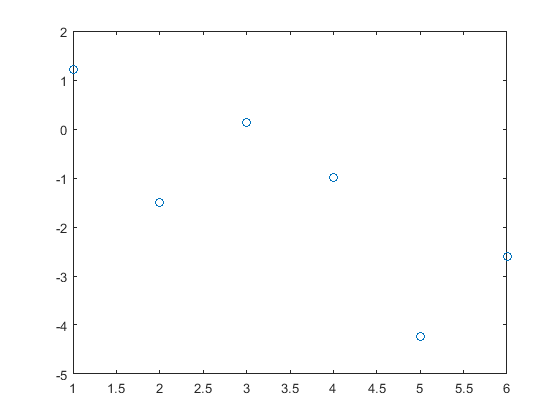

plot(N_realziacji, 'o')

## LITERATURA

[1] L.F. Shampine “*Vectorized Adaptive Quadrature in MATLAB®*,” *Journal of Computational and Applied Mathematics*, 211, 2008, pp.131–140.

[1] Gander, W. and W. Gautschi, “Adaptive Quadrature – Revisited,” BIT, Vol. 40, 2000, pp. 84-101. Dostepne również na:  [`https://people.inf.ethz.ch/gander/`](https://people.inf.ethz.ch/gander/).

aktualizacja: styczeń 2024                                                                                              **© **K. Król and M. Kamiński